# Persephone Tutorial 2: Creating Community Microbiome Models

Authors: Anna Sheehy, Bram Nap, Wiley Barton

Last updated: April 2026

In this tutorial we will cover how to create community microbiome from metagenomic reads data. We will explain how to use Microbial Abundances Retrieved from Sequencing data—automated NCBI Taxonomy (MARS) [1] to map metagenomic reads to AGORA2 database [2]. We will then explain how to process the output of MARS through the Microbiome Modelling Toolbox [3] to generate community microbiome models.

This tutorial will take you step by step through creating community microbiome models. There are four main steps to the process:

- General setup: Core procedures for setting-up the Persephone environment.

- Bioinformatic processing of sequence data (SeqC): Takes you from raw sequence data to taxonomy assigned read counts.

- Micorbial Abundances Retrieved from Sequening data (MARS): Takes you from taxonomy assigned read counts to reative abundances mapped to your chosen microbial reconstruction resource e.g., AGORA2.

- Microbiome model creation with mgPipe: Takes your mapped relative abundance data and creates personalised community micrcobiome models personalised for each sample in your metagenomic data file.

Depending on your data you can start with step 2 (raw reads) or jump to step 3 (assigned taxonomy read counts). An overview of the different input variables, how to create an configuration file, and how to run Persephone is found in Tutorial 1.

## Step 1: Setup

Here we show which steps are required to set up your device to support the various functions used to create and analyse human-microbiome models for Persephone. First we need to have a copy of COBRA toolbox. COBRA Toolbox download instructions can be found at [https://github.com/opencobra/cobratoolbox](https://github.com/opencobra/cobratoolbox)

To see if the COBRA toolbox is installed correctly we run initCobraToolbox

global CBTDIR
if isempty(CBTDIR)
    initCobraToolbox
end

As the function gives no errors or warnings we know that the COBRA toolbox is correctly set-up and ready to use.

To decrease simulation times of the models we need an industrial solver. The different solvers supported are

- ibm_cplex

- tomlab_cplex

- gurobi

- mosek

To see MATLAB version and solver version compatibility see [https://opencobra.github.io/cobratoolbox/stable/installation.html#solver-installation.](https://opencobra.github.io/cobratoolbox/stable/installation.html#solver-installation.) Various solvers can be obtained through an free academic license. For modelling purposes here, we recommomend using ibm_cplex if possible.

To set our solver we use changeCobraSolver. If another solver than ibm_cplex is used, replace the 'ibm_cplex' in the the code line below with the solver name you use as found in the bullet list above.

solver = 'ibm_cplex';
% solver = 'gurobi';

changeCobraSolver(solver);

MATLAB also needs to have two additional toolboxes installed, the Statistics and Machine Learning Toolbox and the Parallel Computing Toolbox. We can check the installations with the code matlab.addons.isAddonEnabled.

% Check the install of the parallel computing toolbox
parallelToolboxInstall = matlab.addons.isAddonEnabled('Parallel Computing Toolbox')

% Check the install of the statistics and machine learning toolbox
statToolboxInstall = matlab.addons.isAddonEnabled('Statistics and Machine Learning Toolbox')

If the parallelEnabled and statisticsEnables are both 1 (true) both toolboxes are correctly installed in MATLAB and ready to be used. If either one is 0 we recommended adding the toolbox from Home tab -> Add-Ons -> Get Add-Ons. The parallel computing toolbox is a must as the code creating the mWMBs does not work without out. The statistics toolbox is not required to create the mWBMs but without it we cannot run the statistical analyses performed in tutorial 5.

Before we can start with creating mWBMs, we need to set up the paths to the general results directory, the metadata file, and the taxonomy assigned reads table. We will use the general results directory to create a folder structure where we can easily store our results in pre-defined locations. This will help as functions generally need the outputs of functions run before them. The metadata and reads tables undergo sanity checks. The variables we will set up are then:

- **resultDir** - The path where all the results of this tutorial will be stored. This ensure all your results will be in one place and are thus easily accesible. Make sure the the folder is accesible to you.

- **metadataPath** - The location of the metadata file. This is used in both the generation of human-microbiome models as well as the analysis of results towards the end of the tutorial.

- **readsTablePath** - The path to the the taxonomic reads file containing the amount of reads per taxonomic assignment. If the taxonomic assignments are in the reads file the first column needs to be called Taxon. If not the first column of the readsFile and the first column of taxaTable needs to have to same name. See the example files.

We set up the variables in the **paths** variable, which is a structure. Each field in the structure is dedicated to store the relevant variables used in the different steps of Persephone. Normally we would define each variable at the start in the configuration file. However here we will only specifiy the output directories used in Persephone. The other variables we will define as we go along for clarity.

Please copy and paste the paths to the required files in the code below. Remember to add file extensions where relevant.

%Define the location of the required files, make sure you dont forget the file extensions where relevant!
% e.g., 'C:\Users\Owner\Persephone\Tutorials\Results'
resultPath = '';

% e.g., 'C:\Users\Owner\cobratoolbox\tutorials\analysis\persephone\Demo\demo_metadata.csv'
paths.General.metadataPath = '';

% e.g., 'C:\Users\Owner\cobratoolbox\tutorials\analysis\persephone\Demo\demoReads.xlsx'
paths.Mars.readsTablePath = '';

Now we will define some paths as to where we want to store all of our results. We do not have to make these directories ourselves, the code will do it for us.

paths.seqC.outputPathSeqC = [resultPath, filesep, 'resultSeqC'];
paths.Mars.outputPathMars = [resultPath, filesep, 'resultMars'];
paths.mgPipe.outputPathMgPipe = [resultPath, filesep, 'resultMgPipe'];
paths.persWBM.outputPathPersonalisation = [resultPath, filesep, 'personalisedWBMs'];
paths.mWBM.outputPathMWBM = [resultPath, filesep, 'mWBMmodels'];
paths.fba.outputPathFluxResult = [resultPath, filesep, 'resultFlux'];
paths.fba.outputPathFluxAnalysis = [paths.fba.outputPathFluxResult, filesep, 'fluxAnalysis'];
paths.stats.outputPathStatistics = [resultPath, filesep, 'resultStatistics'];

The function initPersephone.m performs the initCobraToolbox.m function, sets the COBRA solver and checks if the required toolboxes are installed. Additionaly it generates the folder structure for the results. IMPORTANT, the output structure used in Persephone is generated with initPersephone.m. The metadata and the reads table are put through sanity checks. initPersphpne.m ensures that in the metdata the columns with the sample IDs and sample sex have the correct headers and readable data types. It always assumed the first column contains sample IDs. It will create a new updated file and will also update the metadata path accordingly. If you use the test data files you can see that the column sample ID has been changed to ID and the column gender has been altered to Sex. Additionally the data in the column Sex has been changed from M/F to male/female. Important if your own metadata does not have alternative headers accounted for in the function it will raise an error. That is easily fixed by changing your column headers to ID or Sex depending on which data type is causing the issue. Finally we test if the sample IDs in the microbiome data match that of the metadata.

% Create the file structure for the results of all the parts of the
% tutorial (not just this tutorial)
[initialised, statToolboxInstalled, updatedMetadataPath] = initPersephone(resultPath, paths)

The following ouputs are returned from initPersephone

- **initialised -** Boolean, indicates if Persephone was succesfully initialised.

- **statToolboxInstalled -** Boolean, indicates if the statistics toolbox is installed. Parts of Persephone are skipped if false

- **updatedMetdataPath**  -  The path to the updated metadata file.

If you look at the directory given in the resultPath variable, you will see the following folder structure.

`_/resultDir`

` |__/mWBMmodels`

` |__/personalisedWBMs`

` |__/resultFlux`

` |  |__/fluxAnalysis`

` |__/resultMars`

` |__/resultMgPipe`

` |__/resultSeqC`

` |__/resultStatistics`

The content of each of the folders will be discussed in the appropriate sections in the tutorials.

We have to also update the metadata path to reflect the updated metadata file.

paths.General.metadataPath = updatedMetadataPath;

Now that we have checked that all our software is installed and available, our results directory has been set up and our metadata and read files has been processed and ready for use we can start with processing the metagenomic reads data through MARS.

## Step 2: Bioinformatic processing of sequencing data

### Requirements:

To successfully follow this tutorial, you need to have the following

 installed on your system:

- **Docker Desktop or Engine** (tested@ 4.37.1 (178610))

- **MATLAB** (tested@R2024b)

- **SeqC Repository** (Bioinformatics pipeline for taxonomic classification)

- **Apptainer **(OPTIONAL; Only if operating in an HPC environment)

**IMPORTANT: This step is time-consuming and only advised for those with a desktop set up with a minimum of 20GB RAM, multicore >2.5GHz CPU, and 100GB of free disk space. If working on a computer that does not meet these requirements you can skip to the next section: 'Creating Community Microbiome Models' or expect >1day of run time.

### Introduction

This tutorial is part of a series to support the use of the *Persephone* pipeline. This tutorial goes through the steps of the overall pipeline that interact directly with the *Sequence Conversion (SeqC) *pipeline. SeqC is a Docker-based bioinformatic environment with the purpose of providing a standardised, efficient, and portable means to generate the microbial taxonomic inputs for the rest of Persephone from raw sequencing data. SeqC performs quality control of fastq files with *Kneaddata* [4], taxonomic assignment to reads with a combination of *Kraken2 *[5] and *bracken* [6]--using custom assignment databases derived from AGORA2 [2] and or APOLLO [7], with configuration to accommodate MARS [1]. Sequencing files and a text file containing the unique identifiers of the files are placed in the seqc_input subdirectory and then ouputs are generated to seqc_output, prior to being relocated for additional steps of Persephone.

### Section 1: Environment Preparation

The SeqC pipeline is executed using the `runSeqC` function, which is called by the main `runPersephone` function. This function relies on configurations set in the **configPersephone.m** file.

#### **Downloading SeqC**

SeqC is included in the **COBRA Toolbox**. If you have not installed it yet, follow the instructions available here: [https://github.com/opencobra/cobratoolbox](https://github.com/opencobra/cobratoolbox)

#### **Configuring SeqC Paths**

Once SeqC is installed, you need to specify key file paths in **MATLAB**:

% Character array variable specifying the folder where seqC repository is stored
% e.g., 'C:\Users\cobratoolbox\src\analysis\persephone\SeqC_pipeline'
paths.seqC.repoPathSeqC = '';
% Character array variable specifying the folder
% where the final output of SeqC is stored. By default this is located
% within the parent directory defined in the core results variable:
% resultPath
% e.g., '/Users/_projects/persephone/Demo1_out';
resultPath = '';
% Followed by:
paths.seqC.outputPathSeqC = [resultPath filesep, 'ResultSeqC'];
% The resulting location of seqc results then being:
% '/Users/_projects/persephone/Demo1_out/ResultSeqC'

% *REQUIRED*. Character array variable of the file name
% containing sample IDs for FASTQ files (e.g., sample_id.txt)
paths.seqC.fileIDSeqC = 'sample_id_demo.txt';

It is expected that raw sequencing files in FASTQ format are stored in the *seqc_input* subdirectory of the SeqC repository, along with corresponding sample ID file.

For example:

`~/SeqC_pipeline`

` |__/seqc_input`

`    |__/sample_id_demo.txt`

`    |__/sample_1_R1.fq.gz`

`    |__/sample_1_R2.fq.gz`

`    |__/sample_2_R1.fq.gz`

`    |__/sample_2_R2.fq.gz`

Where sample_id_demo.txt contains:

`sample_1`

`sample_2`

#### Set the paths to all inputs for seqC

These variables control how SeqC processes sequencing data and determines available computational resources.

> Starting MARS
> Loading database
> Renaming and cleaning up of taxonomic assignments
> Mapping and collecting metrics


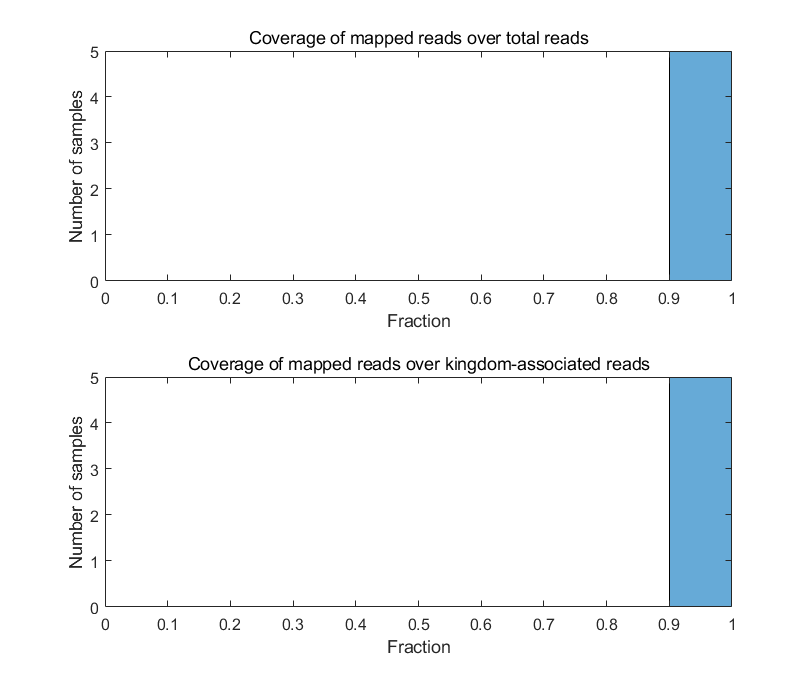

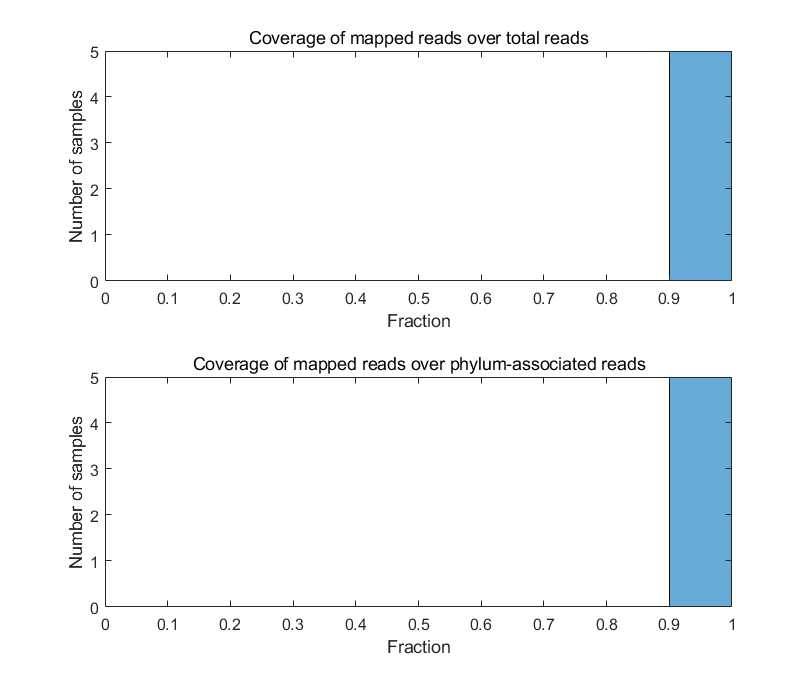

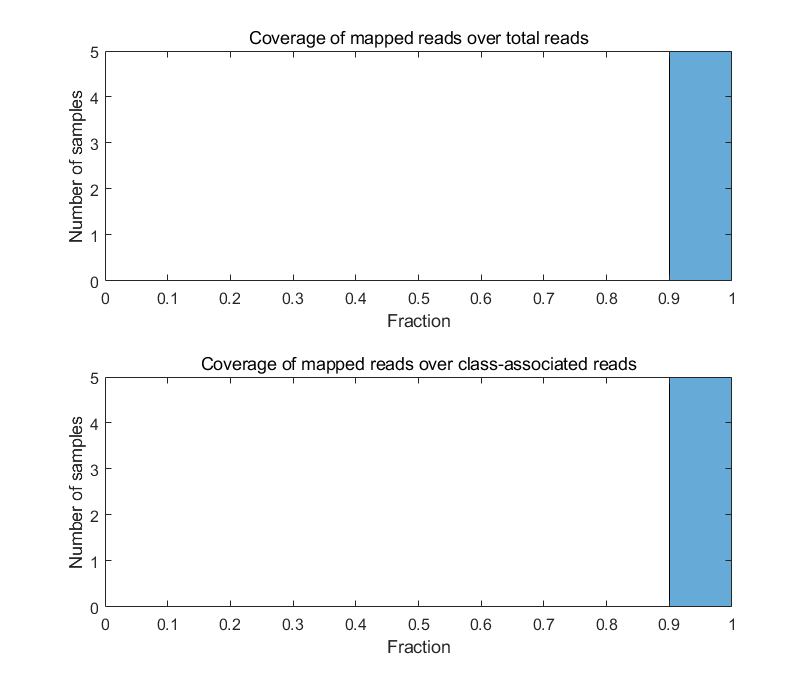

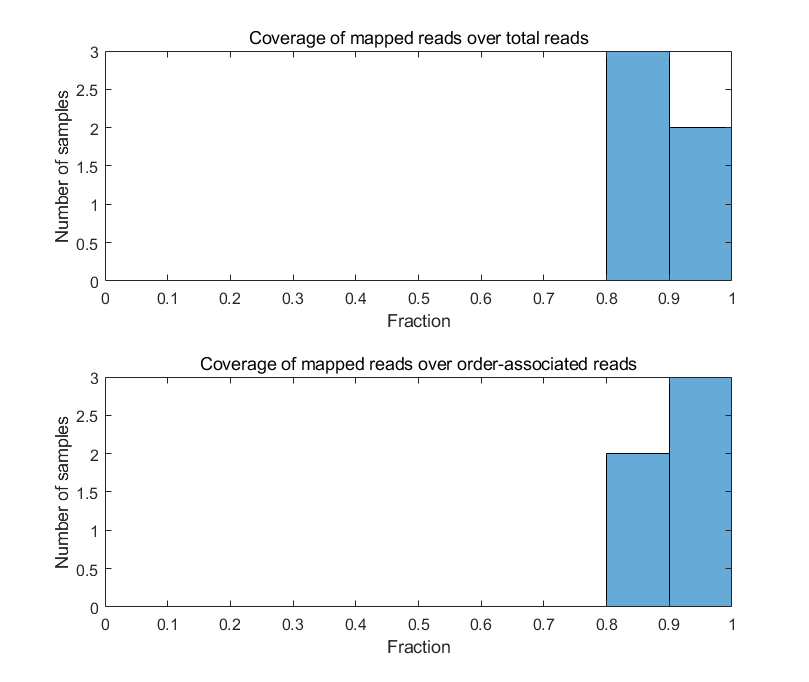

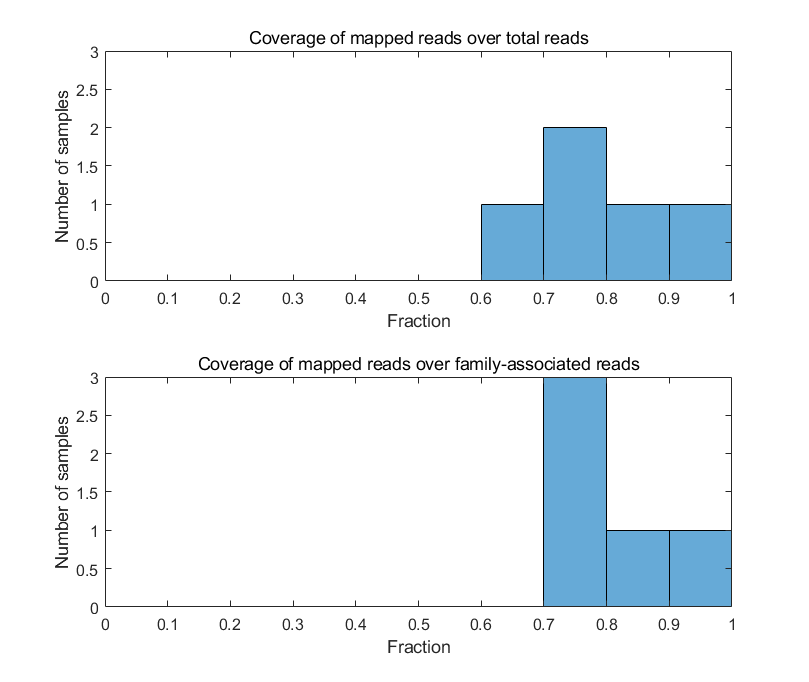

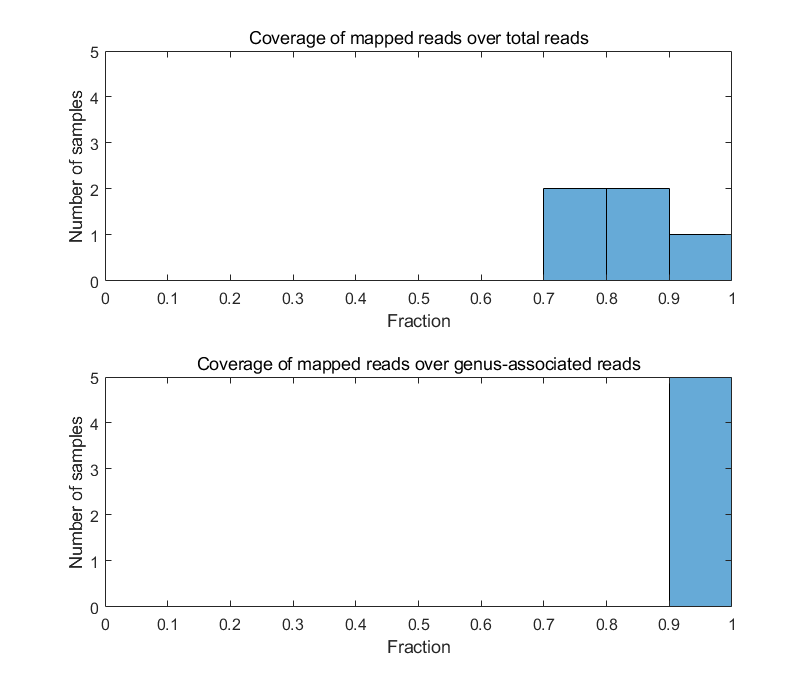

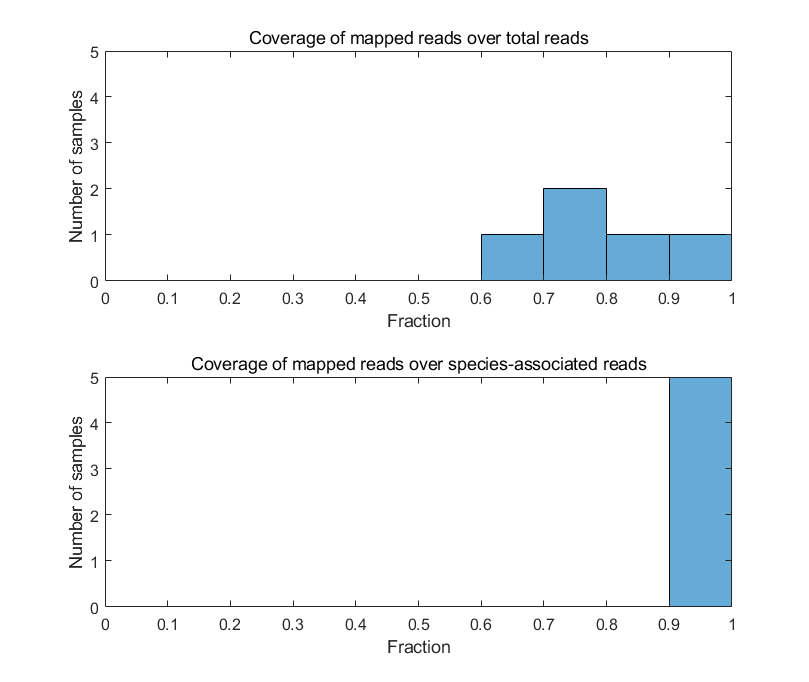

 > Generate metrics visualizations.
> MARS finished sucessfully


% Logical variable indicating if intermediary outputs are
% retained (e.g., post-QC FASTQ). False results in just the

% output of taxonomic profiles (KB_S_mpa_out_RA.txt) and a run log (log_seqc_project.txt),
% and the deletion of all intermediary content once SeqC completes.
paths.seqC.procKeepSeqC = false;

% Numeric, the maximum amount of memory allowed in gigabytes.
paths.seqC.maxMemSeqC = 20;

% Numeric, the maximum number of threads allowed.
paths.seqC.maxCpuSeqC = 4;

% Numeric, the maximum number of processes allowed.
% The multiple of max CPU and max Proc should not exceed the total
% system cores.
paths.seqC.maxProcSeqC = 2;
% Logical variable indicating if additional debugging
% messaging should be included in the log.
paths.seqC.debugSeqC = false;

% If running the pipeline on a HPC system with Apptainer (formerly Singularity)
% installed, the docker image can be converted to .sif format and run via
% Apptainer, enabling resource managment and user permission strategies
% typical to HPC environemnts.
paths.seqC.apptainer = false;

### Section 2: Running SeqC

Ensure **Docker** is running before executing SeqC

The function runSeqC completes the pipeline without interaction once initialised, however for the purpose of instruction, the internal procedure of the function is described.

Now that the environment is set up, you can execute **SeqC** by calling:

runSeqC(...
        paths.seqC.repoPathSeqC, ...
        paths.seqC.outputPathSeqC, ...
        paths.seqC.fileIDSeqC, ...
        paths.seqC.procKeepSeqC, ...
        paths.seqC.maxMemSeqC, ...
        paths.seqC.maxCpuSeqC, ...
        paths.seqC.maxProcSeqC, ...
        paths.seqC.debugSeqC, ...
        paths.seqC.runApptainer ...
        );

runSeqC begins by setting the working directory to that of the SeqC repository, and assessing environmental variables and ensuring they are correctly formatted.

#### **Checking Your Operating System**

The function automatically detects your OS and ensures that **Docker** is properly configured:

%% Determine Operating System
% Some arguments are OS specific
if ismac

numCores = 18

    vOS = 'mac';
    setenv('PATH', [getenv('PATH') ':/usr/local/bin']); % Ensure Docker is found
elseif isunix
    vOS = 'unix';
elseif ispc
    vOS = 'win';
else
    error('Unsupported operating system.');
end
%% Determine availability of Apptainer - 0=ya
% if on system and T in runApptainer, pass with vAPTER=0
[vAPTER, cmdout] = system('which apptainer');
if vAPTER == 0
    if runApptainer
        vAPTER = 0;
    else
        vAPTER = 1;
    end
end

#### **Estimating Disk Usage**

SeqC requires a considerable amount of storage. To estimate space requirements, an optional estimation of the size of outputs generated is calculated below.

%% Determine directory size and estimate usage exapansion
dirPath = fullfile(paths.seqC.repoPathSeqC,'seqc_input/'); % Directory path
totalBytes = getDirectorySize(dirPath); % Function from previous response
totalMB = totalBytes / (1024^2); % Convert to MB
totalGB = totalBytes / (1024^3); % Convert to GB
inflateRatio = 3.2; % inflation term
inflateGB = totalGB * inflateRatio;
msgDsize = sprintf(['Total size of directory: %.2f GB\nExpected ...' ...
    'inflation size: %.2f GB\n'], totalGB, inflateGB);


Before running SeqC, we need to define and initialize key directories. This ensures that the pipeline can correctly locate input files and store output results.

In **MATLAB**, initialize the required paths with:

%% Initialize Paths
vdir_init = cd;
vdir_out_seqc = 'seqc_output';
% Set system to seqc repo
cd(paths.seqC.repoPathSeqC);

Before passing computational resource constraints to the Docker container, we convert numeric values to strings for compatibility. 

%% Convert Numeric Inputs to Strings
maxCpuSeqC = num2str(paths.seqC.maxCpuSeqC);
maxMemSeqC = num2str(paths.seqC.maxMemSeqC);
maxProcSeqC = num2str(paths.seqC.maxProcSeqC);

Then, following command constructs Docker build arguments using the previously converted string values.

The Docker image is built with hardware-specific options, ensuring proper resource allocation. The run command is configured for interactive and non-interactive execution, adapting to system constraints.

%% Build Docker Options
% User ID params
if strcmp(vOS, 'unix')
    [~, v_uid] = system('id -u');
    [~, v_gid] = system('id -g');
    % Strip newline characters
    v_uid = strtrim(v_uid);
    v_gid = strtrim(v_gid);
    comm_build_opt_UID = sprintf('--build-arg USER_UID=%s --build-arg USER_GID=%s', v_uid, v_gid);
elseif strcmp(vOS, 'mac')
    % fixed for OSX jank
    v_uid = num2str(42069);
    v_gid = num2str(42069);
    comm_build_opt_UID = sprintf('--build-arg USER_UID=%s --build-arg USER_GID=%s', v_uid, v_gid);
elseif strcmp(vOS, 'win')
    % fixed for windows jank
    v_uid = num2str(42069);
    v_gid = num2str(42069);
    comm_build_opt_UID = sprintf('--build-arg USER_UID=%s --build-arg USER_GID=%s', v_uid, v_gid);
end
% Hardware params
comm_build_opt_hw = sprintf('--build-arg varg_cpu_max=%s --build-arg varg_mem_max=%s --build-arg varg_proc_max=%s', ...
                            maxCpuSeqC, maxMemSeqC, maxProcSeqC);
%% Build Docker Image command
comm_build = sprintf('docker build -t dock_seqc --ulimit nofile=65536:65536 %s %s .', comm_build_opt_hw, comm_build_opt_UID);
%% Docker run commands
if vAPTER == 0
    %% Apptainer commands
    % Build from docker image
    comm_build_apter = 'apptainer build apter_seqc.sif docker-daemon://dock_seqc:latest';
% Run statement
    comm_run_core = 'apptainer exec --cwd /home/seqc_user/seqc_project --writable-tmpfs --no-mount tmp --no-home -e';
    comm_run_dir_I = '--mount type=bind,src=$(pwd)/seqc_input,dst=/home/seqc_user/seqc_project/step0_data_in';
    comm_run_dir_O = '--mount type=bind,src=$(pwd)/seqc_output,dst=/home/seqc_user/seqc_project/final_reports';
    comm_run_dir_P = '--mount type=bind,src=$(pwd)/seqc_proc,dst=/DB';
    comm_run_main = sprintf('%s %s %s %s apter_seqc.sif /bin/bash',comm_run_core,comm_run_dir_I,comm_run_dir_O,comm_run_dir_P);
elseif strcmp(vOS, 'unix')
    % core run command
    comm_run_core = sprintf('docker run --tty --user %s:%s --rm --memory=%s --cpus=%s',v_uid,v_gid,sprintf('%sg',maxMemSeqC),maxCpuSeqC);
    % Append volume mapping commands to core
    comm_run_dir_I = '--mount type=bind,src=$(pwd)/seqc_input,dst=/home/seqc_user/seqc_project/step0_data_in';
    comm_run_dir_O = '--mount type=bind,src=$(pwd)/seqc_output,dst=/home/seqc_user/seqc_project/final_reports';
    comm_run_dir_P = '--mount type=bind,src=$(pwd)/seqc_proc,dst=/DB';
    comm_run_main = sprintf('%s %s %s %s dock_seqc /bin/bash',comm_run_core,comm_run_dir_I,comm_run_dir_O,comm_run_dir_P);
elseif strcmp(vOS, 'mac')
    comm_run_core = sprintf('docker run --tty --user 0 --rm --memory=%s --cpus=%s',sprintf('%sg',maxMemSeqC),maxCpuSeqC);
    comm_run_dir_I = '--mount type=bind,src=$(pwd)/seqc_input,dst=/home/seqc_user/seqc_project/step0_data_in';
    comm_run_dir_O = '--mount type=bind,src=$(pwd)/seqc_output,dst=/home/seqc_user/seqc_project/final_reports';
    comm_run_dir_P = '--mount type=bind,src=$(pwd)/seqc_proc,dst=/DB';
    comm_run_main = sprintf('%s %s %s %s dock_seqc /bin/bash',comm_run_core,comm_run_dir_I,comm_run_dir_O,comm_run_dir_P);
    system("chmod -R a+rw ./seqc_input ./seqc_output ./seqc_proc"); % allow interaction from host:dock
elseif strcmp(vOS, 'win')
    comm_run_core = sprintf('docker run --tty --user %s:%s --rm --memory=%s --cpus=%s',v_uid,v_gid,sprintf('%sg',maxMemSeqC),maxCpuSeqC);
    comm_run_dir_I = sprintf('--mount "type=bind,src=%s\\seqc_input,target=/home/seqc_user/seqc_project/step0_data_in"', pwd);
    comm_run_dir_O = sprintf('--mount "type=bind,src=%s\\seqc_output,target=/home/seqc_user/seqc_project/final_reports"', pwd);
    comm_run_dir_P = sprintf('--mount "type=bind,src=%s\\seqc_proc,target=/DB"', pwd);
    comm_run_main = sprintf('%s %s %s %s dock_seqc /bin/bash',comm_run_core,comm_run_dir_I,comm_run_dir_O,comm_run_dir_P);
end

The user can select a taxonomic database (AGORA, APOLLO, or combined) based on user input and constructs a command to run the database creation script with the chosen database and a human contamination filter.

%% Set Database Assignment Command
reconstructionDb = 'full_db'; % Default for now - to be user input
switch reconstructionDb
    case 'AGORA'
        comm_run_db_kb = '"tool_k2_agora"';
    case 'APOLLO'
        comm_run_db_kb = '"tool_k2_apollo"';
    case 'full_db'
        comm_run_db_kb = '"tool_k2_agora2apollo"';
    case 'smol_db'
        comm_run_db_kb = '"tool_k2_std8"'; % smol test db
    otherwise
        comm_run_db_kb = '"tool_k2_agora2apollo"'; % Default case
end
% Default host contaminant db
comm_run_db_kd = '"host_kd_hsapcontam"';
comm_run_db = sprintf('BASH_seqc_makedb.sh -s %s -s %s', comm_run_db_kd, comm_run_db_kb);
comm_mama_db = sprintf('-d %s -d %s', comm_run_db_kd, comm_run_db_kb); % to include in main run rather sep DB



Next, we construct the command to run the SeqC pipeline, optionally appending flags for debugging and keeping intermediate files based on user settings. We then format the full command with input data directory, sample IDs, and other required parameters.

%% Construct Command for Running SeqC
comm_mama_help = 'BASH_seqc_mama.sh -v';
comm_mama_full = 'BASH_seqc_mama.sh';
% append optional flags
if debugSeqC
    comm_mama_full = [comm_mama_full ' -b'];
end
if procKeepSeqC
    comm_mama_full = [comm_mama_full ' -k'];
end
comm_mama_full = sprintf('%s -i "step0_data_in/" -n "%s" -r "SR" -s 0 %s', comm_mama_full, fileIDSeqC, comm_mama_db);


Next, we construct the command to run the SeqC process in a Docker container, adjusting the volume and directory mappings based on the operating system (Unix, Mac, or Windows). This binds input and output directories and specifies where the processing data will be stored within the container.

% Append volume mapping commands to core
% OS sensitive
if strcmp(vOS, 'unix')
    comm_run_main = sprintf(['%s "type=bind,src=$(pwd)/seqc_input,target=/home/...'...
        'seqc_user/seqc_project/step0_data_in" --mount "type=bind,src=$(pwd)/...' ...
        'seqc_output,...' 'target=/home/seqc_user/seqc_project/final_reports" ...' ...
        '--mount "type=volume,...' 'dst=/DB,volume-driver=local,...' ...
        'volume-opt=type=none,volume-opt=o=bind,...' 'volume-opt=device=$(pwd)/...' ...
        'seqc_proc" dock_seqc /bin/bash'], comm_run_core);
%    comm_exit_mv = 'mv -r $(pwd)/seqc_proc/DEPO_proc/* $(pwd)/seqc_output'
elseif strcmp(vOS, 'mac')
    comm_run_main = sprintf(['%s "type=bind,src=$(pwd)/seqc_input,target=/home/...'...
        'seqc_user/seqc_project/step0_data_in" --mount "type=bind,src=$(pwd)/...' ...
        'seqc_output,...' 'target=/home/seqc_user/seqc_project/final_reports" ...' ...
        '--mount "type=volume,....' 'dst=/DB,volume-driver=local,...' ...
        'volume-opt=type=none,volume-opt=o=bind,...' 'volume-opt=device=$(pwd)/...' ...
        'seqc_proc" dock_seqc /bin/bash'], comm_run_core);
%    comm_exit_mv = 'mv -r $(pwd)/seqc_proc/DEPO_proc/* $(pwd)/seqc_output'
elseif strcmp(vOS, 'win')
    comm_run_main = sprintf(['%s "type=bind,src=%s\\seqc_input,target=/home/...'...
        'seqc_user/seqc_project/step0_data_in" --mount "type=bind,src=%s\\...' ...
        'seqc_output,....' 'target=/home/seqc_user/seqc_project/...' ...
        'final_reports" --mount "type=bind,...' 'src=%s\\seqc_proc,...' ...
        'target=/DB" dock_seqc /bin/bash'], comm_run_core, pwd, pwd, pwd);
%    comm_exit_mv = 'mv -r .\seqc_proc\DEPO_proc\* .\seqc_output\'
end

### Section 3: Running Docker for SeqC

SeqC runs within a **Docker container**. The following commands:

- Build the **Docker image** if it does not exist

- Run the **SeqC pipeline**

#### **Step 1: Build the Docker Image**

Once all the variables and Docker statements are constructed, Docker is engaged and an image of SeqC is created if a previous image is not found. If running with Apptainer, a corresponding .sif is checked for and build if missing. 

%% Run Commands
try
    % check for preexisting image
    imageName = 'dock_seqc';
    [status, cmdout] = system(['docker images -q ' imageName]);
end

if isempty(strtrim(cmdout))
    disp(['Image "' imageName '" does NOT exist. Now creating...']);
    disp(' > Building SeqC docker image, wait time ~15min.');
    [status, cmdout] = system(comm_build);
    if status ~= 0, error('Docker build failed:\n%s', cmdout); end
else
    disp(['Docker Image "' imageName '" exists.']);
end
if vAPTER == 0
    % check for preexisting image
    imageName = 'apter_seqc.sif';
    %[status, cmdout] = system(['docker images -q ' imageName]);
    if isfile(imageName)
        disp(['Apptainer Object "' imageName '" exists - BUILD SKIPPED']);
    else
        disp(' > Building SeqC Apptainer/Singularity image, wait time ~15min...again');
        [status, cmdout] = system(comm_build_apter);
        if status ~= 0, warning('Apptainer/Singularity build failed:\n%s', cmdout); end
    end
end

#### **Step 2: Run the Pipeline**

Once the Docker image is built, the following commands that will:

- Test to confirm image viability

- Establish required databases

- Proccess sequencing files

First we run a test of the MAMA script to verify if the Docker image and related commands work correctly. If it fails, a warning is displayed.

% Test MAMA script
    [status, cmdout] = system(sprintf('%s %s',comm_run_main, comm_mama_help));
    if status ~= 0, warning('MAMA test failed:\n%s', cmdout); end

Next we must initiate the database setup for the pipeline, with an estimated wait time of 30 minutes.

% Run database creation
    disp(' > Running database setup, wait time ~30min....');
    [status, cmdout] = system(sprintf('%s %s',comm_run_main, comm_run_db));
    if status ~= 0, error('Database setup failed:\n%s', cmdout); end

And finaly, this command starts the full SeqC processing pipeline:

% Run full SeqC pipeline
    disp(sprintf(' > SeqC Processing Begins...\n%s',msgDsize));
    %sprintf('%s %s',comm_run_main, comm_mama_full) % TS - display final command
    [status, cmdout] = system(sprintf('%s %s',comm_run_main, comm_mama_full));
    if status ~= 0, error('SeqC pipeline execution failed:\n%s', cmdout); end
    disp(' > SeqC Processing Ends.');

### Section 4: Managing Output Files

After processing, results are stored in the **outputPathSeqC** folder. The working directory is then restored.

% Move final output
movefile(fullfile(vdir_out_seqc, '*txt'), outputPathSeqC);
% Restore original directory
cd(vdir_init);

## Step 3: Running MARS

In this section we will run MARS to convert the taxonomic reads table to AGORA2 mapped and normalised relative abundance table. MARS works as following:

- First, if the taxonomic assignments and reads tables are separated - it will merge them into a single dataframe

- It removes clade extensions from all taxonomic levels names (e.g. Firmicutes__A & Firmicutes__B will be merged to Firmicutes) to allow for optimal AGORA2 mapping

- It translates certain species based on a pre-defined list to make sure the species names match the ones in the AGORA2 databases

- It removes all reads associated with a taxonomics identification that does not have information up to the specified taxonomic level that is looked at (e.g., looking at species, only reads with information up to the species level will be retained)

- It maps each taxonomic level (kingdom, phylum,species etc.) to the AGORA2 databases. If the taxonomic identification matches it means there is a model present

- The mapped reads are normalised to obtain relative abundances

- All relative abundances under a certain cutoff are removed and the data is re-normalised. The default cutoff is 1e-6.

Important before running this section is that MARS can also be ran online in your browser on [https://mars-pipeline.streamlit.app.](https://mars-pipeline.streamlit.app.) The website explains what you have to input and the variables you can use are the same as explained here. Important is that you download the present_species.csv file (file exentsion can differ) and save it in either the 'present' directory in resultMARS named as 'present_species.csv' or give the correct path to MgPipe (discussed in the next section) This ensures that we the MARS output file can still be found by the rest of the functions.

If we want to run MARS offline you must just prepare your MARS inputs

Required inputs

- **readsTable** - The path to the the taxonomic reads file containing the amount of reads per taxonomic assignment. If the taxonomic assignments are in the reads file the first column needs to be called Taxon. If not the first column of the readsFile and the first column of taxaTable needs to have to same name. See the example files. (we set this already at the start)

- **taxaTablePath** - The path to the taxonomic assignments for the taxomomic unit name used in your taxonomic assignment software (e.g., OTU, ASV, OGU). This has to be set to string(missing) if your readsTable already has taxonomic assignment included. Otherwise it need to consists of a column with header similar to the first header in readsTable and the column header "Taxon".

- **outputPathMars** - The path where the MARS results should be stored. We created this directory in the section 1 and is stored in paths.mars.

Optional inputs

- **sampleReadCountsCutoff** - Numeric value for total read counts per sample under which samples are excluded from analysis. Only applies when readsTable contains absolute read counts (not relative abundances). Defaults to 1, with minimum of 1.

- **cutoffMars** - The cutoff underwich all relative abundances will be considered 0. If smaller relative abundances are kept, numerical difficulties/infeasibilites could occur later on when solving the microbiome models. Also, relative abundances below this value will most likely not have a noticable impact on the flux results as their contribution to fluxes is minimal due to their low relative abundance. Default is 1e-6.

- **flagLoneSpecies** - A boolean, flagLoneSpecies, which is true if the species name does NOT have the genus name already there. False if otherwise. Defaults to false.

- **taxaDelimiter** - A string,  taxaSplit, which indicates the delimiter used to separate taxonomic levels in the taxonomic assignment.Defaults to ';'. 

- **removeClade** - A boolean, removeClade, which removes all reads associated with a taxonomics identification that does not have information up to the specified taxonomic level that is looked at. Defaults to true.

- **reconstructionDb**: A string defining if AGORA2, APOLLO, a combination of both or a user-defined database should be used as model database to check presence in.  Allowed Input (case-insensitive): "AGORA2", "APOLLO", "full_db", "user_db". Defaults to "full_db".

- **userDbPath**: A string containing the full path to the user-defined database, which should be in .csv, .txt, .parquet or .xlsx format and have column names = taxonomic levels. Only required if 'whichModelDatabase' is set to "user_db". Note, that the user database needs to have the same structure as the integrated AGORA2 & APOLLO database to function properly!

- **calculateBrayCurtis**: Boolean to indicate if Bray Curtis should be calculated for microbiome samples. Defaults to false.

- **compoundedDatabase**: Boolean; specifies is the reads table is compounded or not. Compounded  here means that the reads for a specific taxonomic level are taking into  account the taxonomic level above it.

We know now which inputs we need to define. Let us start with the required ones.

% Set the path to your reads table
readsTablePath = paths.Mars.readsTablePath;

% Set the path the taxaTablePath.
taxaTablePath = '';

% The output path stored in the paths variable
outputPathMars = paths.Mars.outputPathMars; % This is the default path created by initPersephone

Now let us set the optional inputs. You can change these according to your own dataset, for the test data set we recommend using the settings set here.

% Numeric value for total read counts per sample under which samples are
% excluded from analysis. Only applies when readsTable contains absolute
% read counts (not relative abundances). Defaults to 1, with minimum of 1.
sampleReadCountsCutoff = 1;

% The cutoff value for relative abundances
cutoffMars = 1e-6;

% The flag if genus name is in the species name
flagLoneSpecies = true;

% The delimeter used to separate taxonomic levels
taxaDelimiter = ';';

% A boolean specifying if one wants to remove clade name extensions from
% all taxonomic levels of microbiome taxa. If set to false, MARS might find
% significantly less models in AGORA2, as clade extensions are not included
% there.
removeClade = true;

% A string defining if AGORA2, APOLLO, a combination of both or a user-defined
% database should be used as model database to check presence in. 
% Allowed Input (case-insensitive): "AGORA2", "APOLLO", "full_db", "user_db".
% Default: "full_db".
reconstructionDb="full_db";

% A string containing the full path to the user-defined database,
% which should be in .csv, .txt, .parquet or .xlsx format and
% have column names = taxonomic levels. Only required if whichModelDatabase
% is set to "user_db".
userDbPath="";

% Boolean to indicate if Bray Curtis should be calculated for microbiome
% samples. Defaults to false.
calculateBrayCurtis = false;

% Boolean; specifies is the reads table is compounded or not. Compounded 
% here means that the reads for a specific taxonomic level are taking into 
% account the taxonomic level above it
compoundedDatabase = false;

With the optional arguments set we can run MARS

% Run MARS to perform metagenomic mapping
    runMars(readsTablePath, ...
        'cutoffMars', cutoffMars, ...
        'flagLoneSpecies', flagLoneSpecies, ...
        'taxaDelimiter', taxaDelimiter, ...
        'removeClade', removeClade, ...
        'reconstructionDb', reconstructionDb, ...
        'userDbPath', userDbPath, ...
        'sampleReadCountCutoff', sampleReadCountsCutoff, ...
        'taxaTablePath', taxaTablePath, ...
        'outputPathMars', outputPathMars, ...
        'calculateBrayCurtis', calculateBrayCurtis, ...
        'compoundedDatabase', compoundedDatabase...
        );

% return back to the result directory
cd(outputPathMars);

% Set the relative abundance file path to be used by other functions
relAbunFilePath = [paths.Mars.outputPathMars, filesep, 'mapped_forModelling', filesep,...
   'mapped_forModellingSpecies.csv'];

If MARS finished succesfully then you can find the results in the resultMars directory. 

- metrics - For each taxonomic level, various metric such as alpha and beta diversity are calculated.

- mapped - For each taxonomic level, only the reads of the mapped taxa are reported.

- processed - For each taxonomic level, the reads are reported after processing. This can be used to understand the effect of processing on the original metagenomics. 

- unmapped - For each taxonomic level, only the reads of the unmapped taxa are reported.

- mapped_forModelling - For  each taxonomic level, the mapped taxa are normalised so that each column adds up to 1.

The file mapped_forModellingSpecies.csv (file extension can change based on user input) in the "mapped_forModelling” directory is used as input to create community microbiome models. We can expect for about 70-80% of the total reads to be able to be mapped to the AGORA2 database if you use whole-genome shotgun data. Using 16s sequencing, this can drop to 30-40%, mostly because many of the reads do not have information on the species level and are automatically discarded.

NOTE: If in the processed_Species file has many species absent it might be worthwile to see if homosynonyms can be found. You can either do this manually or run your list of absent species throught the MARS-ANT pipeline that checks for homosynonyms and presence in the AGORA2 resources. [https://mars-pipeline.streamlit.app.](https://mars-pipeline.streamlit.app.) Again If the online app is used, please store the files in the appropriate location in your resultDir we defined at the beginning of this part of the tutorial. This allows for seemless integration with the other function and eliminates the need to generate new path variables. If you did fine homosynomys manually, you will need to adjust the names of your taxonomic assignments in either the readsTable or the taxaTablePath and rerun MARS.

## Step 4: Creating microbiome community models

In this section we will create community microbiome models using the Microbiome Modelling Toolbox 2.0 [3]. We will use here pan-species models from the AGORA2 resource [2]. Pan-species means that all the strains of a species were combined into one general model that has all the metabolic capabilities of the individual strains. This is done as metagenomic sequencing usually can only distinguish up untill the species level. We will explain how to pipeline generates community metabolic models and how to call on the pipeline (MgPipe). The microbiome modelling toolbox does the following:

- It transforms all microbial reconstructions present in the relative abundance file. The external compartment is changed from [e] to [u] and reactions names are adapted. This is done to prepare the models to exchange with the internal environment of the microbiome [u].

- All metabolites that each microbial reconstruction can exchange with its environment are stored

- All reactions present in each reconstruction are stored as well as their associated subsystems. These will be used to calculate reactionsPresence, reactionAbundance and subsystemAbundance and can be used to describe the metabolic capabilities of indiviual microbioem models.

- All microbe reconstructions that are present in a sample are added together in one big model. The reconstructions can exchange metabolites in the [u] compartment created in the beginning of the function. The microbiome model can exchange metabolites with the outside environemt by transporting metabolites from [u] to [e] and vice versa.

- A microbiome biomass reaction is formulated which looks like: a microbe1 + b micobre2 + c microbe3 + ... The letters a,b and c are the relative abundance for the respective microbes as found in the relative abundance file we calculated via MARS.

- A standard diet is added to the microbiome models and checked if the total growth rate of 1 microbiome exchange per day (read as 1 fecal exchange per day) can be reached.

- Statistics on total amount of reactions, metabolites and microbes for each microbiome are collected and plotted in violin plots.

To run MgPipe we need to understand the inputs required. NOTE: we here only use a small subset of inputs for MgPipe, if you want a more detailed explanation of the various inputs for the pipeline please look at [https://github.com/opencobra/COBRA.tutorials/tree/0d5becf7171844e53d3d43437035917a2bd9cc61/analysis/microbiomeModelingToolbox.](https://github.com/opencobra/COBRA.tutorials/tree/0d5becf7171844e53d3d43437035917a2bd9cc61/analysis/microbiomeModelingToolbox.) Which is also a tutorial in the COBRA toolbox.

Required inputs

- **microbeReconstructionPath** - The path to the directory with the pan-species models. These can be downloaded from: 

                AGORA2 pan-species reconstructions: [https://doi.org/10.7910/DVN/LAO2XM](https://doi.org/10.7910/DVN/LAO2XM)

                APOLLO pan-species reconstructions: [https://doi.org/10.7910/DVN/PIZCBI](https://doi.org/10.7910/DVN/PIZCBI)

                AGORA2+APOLLO pan-species reconstructions: [https://doi.org/10.7910/DVN/JAXTWY](https://doi.org/10.7910/DVN/JAXTWY)

- **relAbunFilePath** - The path to the file with the AGORA2 mapped relative abundances. This is the mapped_forModellingSpecies.csv file created by MARS in section 2. If you have just run Mars default directory stucture will be assumed. Otherwise you have to define it yourself to point towards your relative abundance file.

- **computeProfiles** - A boolean (true or false) that tells the pipeline if we want to calculate the exctretion and uptake profiles of the microbiome models. We will not do this during this tutorial. However if you are more interested in the microbiome output, you can put this variable to true. This is a time-consuming step and is sped-up by using ibm_cplex as solver. For more information on the extra output if this is set to true look at this tutorial in the COBRA toolbox [https://github.com/opencobra/COBRA.tutorials/tree/0d5becf7171844e53d3d43437035917a2bd9cc61/analysis/microbiomeModelingToolbox](https://github.com/opencobra/COBRA.tutorials/tree/0d5becf7171844e53d3d43437035917a2bd9cc61/analysis/microbiomeModelingToolbox)

Optional inputs

- **solver: **your chosen solver (see above)

- **numWorkersCreation** - Number of workers you want to use for parellelisation. More workers means faster computing times. If you are unsure about the value, follow instructions in the code below. That will help make a decision.

- **outputPathMgPipe** - The path where the mgpipe results and the microbiome community models will be stored. The directory is stored in the paths variable created in section 1

We know how MgPipe works and which inputs we need, we will now define the variables.

% The path to the pan-species directory
% e.g., 'C:/Users/Owner/APOLLOAGORA/panSpecies'
microbeReconstructionPath = '';

% Set computeProfiles variable
computeProfiles = false;

% Set mgPipeRes variable
outputPathMgPipe = paths.mgPipe.outputPathMgPipe;

% Set diet 
Diet = 'EUAverageDiet'

% Create diet text file and extract path
dietPath = validateDietPath(Diet, resultPath)

It can be difficult if you are unfamiliar with the concept to define the number of workers you want to use. Here as some tips you can use. Running "feature('numcores')" will tell you the amount of available cores on your device. An automatic way of chosing your amount of workers is by taking 80% of the available cores on your device which leaves cores available for non-MATLAB related tasks. If working on a cluster or if the device is not required for anythin else, take all available cores. This is recommended when the numCores is greater than 4. If smaller you want want to set the amount of cores to 2 or 3. You cannot go lower than 2 workers. Below is the code that sets the numworkers for you. 

% Find how many available cores you have
numCores = feature('numcores')
% Set the number of workers manually. You can change this value.
%numWorkersCreation = 10;

% Remove the % at line 106 if you want to use all cores. This will overwrite
% the workers set in line 104.
% numWorkersCreation = numCores;

% Remove the % at line 108 if you want to use 80% of the cores. This will overwrite
% the workers set in line 104 or 108 if active.
numWorkersCreation = floor(feature('numCores')*0.8);

Now that we have set all our inputs we can run MgPipe with the initMgPipe.m function.

% Run MgPipe COPY IN THE COMMAND WINDOW AND RUN FROM THERE. 
% IF RUN IN MLX IT WILL FREEZE YOUR MLX FILE AND YOU WILL NEED TO RESTART MATLAB
% AND COPY AND PASTE THE ENTIRE FILE TO A NEW.MLX VERSION
%   initMgPipe( ...
%         microbeReconstructionPath, ...
%         relAbunFilePath, ...
%         computeProfiles,... 
%         'solver', solver, ...
%         'numWorkers',numWorkersCreation, ...
%         'resPath', outputPathMgPipe, ...
%         'Diet', dietPath);

Warnings might pop up such as

- Individual health status not declared. Analysis will ignore that

- Directory already exists

- The temporary variable 'loadDiet' will be cleared at the beginning of each iteration of the parfor-loop. If 'loadDiet' is used before it is set, a runtime error will occur

- Column headers from the file were modified to make them valid MATLAB identifiers before creating variable names for the table. The original column headers are saved in the VariableDescriptions property. Set 'VariableNamingRule' to 'preserve' to use the original column headers as table variable names.

- Reaction x not in model

- File 'simRes.mat' not found.

- File 'intRes.mat' not found.

These warnings are expected to occur and can be safely ignored. Press Run Section in the Live Editor to run the MgPipe function.

If the followig errors occurs, follow the advice below

**ERROR: Modelname cant be found (you dont have the model in the directory or there is some sort of misspelling in the filenames)**

If no errors popped up the microbiome models should now have been created. You can find them in your output folder under mgpipeResults. There you also find the csv files:

- GrowthRates - It gives the maximum growth rate of each microbiome under a rich diet and a pre-defined diet. 

- ModelStatistics - for each microbiome model it gives the total amount of reactions, metabolites and microbes. MicrobiomeModel_sizes.png is a visual representation of this information.

- ModelStatsSummary - gives you the mean, median, min and max of the amount reactions metabolites and microbes considering all microbiome models. 

- ReactionAbundance - gives the relative abundance of a reaction for each metabolic reaction in each microbiome model. Reaction abundances are based on the relative abundance of the microbe and wether or not the microbe has that specific reaction.

- ReactionPresence - says if a reaction is present in at least 1 microbe in a microbiome model.

- SubsystemAbundance - the same as reactionAbundance, however now all reactions are assigned a subsystem and abundances for the same subsystems are summed.

You will also find .mat files of the microbiome models unconstrained (mirobiota_model_samp_sample ID) or diet constrained (folder Diet, microbiota_model_diet_sample ID). The individual microbe modelsused to create the microbiome models are stored in the modelStorage folder. infeasModels.mat has information on models that could not produce biomass. mapInfo.mat is used to hotstart the pipeline in case there were errors or MATLAB was unexpectly stopped or crashed during execution of the pipeline.

This is the end of Tutorial 2.

# References (APA style)

[1] Hulshof, T., Nap, B., Martinelli, F., & Thiele, I. (2024). Microbial abundances retrieved from sequencing data—automated NCBI taxonomy  (MARS): a pipeline to create relative microbial abundance data for the  microbiome modelling toolbox and utilising homosynonyms for efficient  mapping to resources. *Bioinformatics Advances*, vbae068.

[2] Heinken, A., Acharya, G., Ravcheev, D. A., Hertel, J., Nyga, M., Okpala, O. E., ... & Thiele, I. (2020). AGORA2: Large scale reconstruction  of the microbiome highlights wide-spread drug-metabolising capacities. *BioRxiv*, 2020-11.

[3] Heinken, A., & Thiele, I. (2022). Microbiome Modelling Toolbox 2.0:  efficient, tractable modelling of microbiome communities. *Bioinformatics*, *38*(8), 2367-2368.

[4] https://huttenhower.sph.harvard.edu/kneaddata

[5] Wood, D. E., Lu, J., & Langmead, B. (2019). Improved metagenomic analysis with Kraken 2. *Genome biology*, *20*(1), 257.

[6] Lu, J., Breitwieser, F. P., Thielen, P., & Salzberg, S. L. (2017). Bracken: estimating species abundance in metagenomics data. *PeerJ Computer Science*, *3*, e104.

[7] Heinken, A., Hulshof, T. O., Nap, B., Martinelli, F., Basile, A., O’Brolchain, A., ... & Thiele, I. (2025). A genome-scale metabolic reconstruction resource of 247,092 diverse human microbes spanning multiple continents, age groups, and body sites. *Cell Systems*, *16*(2).